# Condition analysis processing

### Analyze the whisking and seperate the neuronal data into the experimntal conditions

**Load ephys exp**

clear 
clc
close all

experiment = loadExp

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

Preprocess the whisking data

% extract whisking data to a variable
whisking = experiment.Whisking.Raw

whisking = 902555×1 single column vector
    1.8744
    1.8744
    1.7351
    1.7351
    0.5930
    2.4611
    1.6733
    2.6305
    2.2434
   -0.2245


% Build band pass filter
Fs = 400; % sf of video 400 frames per second
[b,a] = butter(5,[0.1,100]/200,'bandpass');
whisking_filtered = filtfilt(b,a,double(whisking));

% envelope whisking data
[whisk_envlope,~] = envelope(whisking_filtered);

% smooth whisking data
sigma = 0.2 * Fs; % 200ms kernel
smoothedEnv = imgaussfilt(whisk_envlope, sigma);


% optional plots
figure; plot(whisking) % filtered data
figure; plot(whisking_filtered) % filtered data
figure; plot(whisk_envlope) % envelope
figure; plot(smoothedEnv) % smoothed data

Identify Whisking events

% detrmine threshold 
thershold = 0.8*std(smoothedEnv)


% get times above threshold
whiskingBinary = smoothedEnv > thershold;
cc = bwconncomp(whiskingBinary); % seperate events to continuous ones

% find the whisking epochs and classifay them according to duration
epochs = zeros(cc.NumObjects, 3); % structure: [start, end, type]
minumumDuration = 0.5; % deterine the minumum amountfor epoch
longEpoch = 5; % determine the cut off between long and short epochs

for i = 1:cc.NumObjects
    epochs(i, 1) = cc.PixelIdxList{i}(1);   % start
    epochs(i, 2) = cc.PixelIdxList{i}(end); % end
    duration = (epochs(i, 2) - epochs(i, 1)) / Fs;
    
    if duration > 0.5 && duration <= 5
        epochs(i, 3) = 1; % Short epoch
    elseif duration > 5
        epochs(i, 3) = 2; % Long epoch
    end
end

visualize epochs

figure;
plot(smoothedEnv, 'b'); % Original signal
hold on;
maxY = 3000;
for i = 1:size(epochs, 1)
    startX = epochs(i, 1);
    endX = epochs(i, 2);
    
    if epochs(i, 3) == 1
        fill([startX, endX, endX, startX], [0, 0, maxY, maxY], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    elseif epochs(i, 3) == 2
        fill([startX, endX, endX, startX], [0, 0, maxY, maxY], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
end

hold off;
xlabel('Sample Index');
ylabel('Amplitude');
title('Detected Whisking Epochs');

if epochs(end,2) > length(experiment.Cams.whisking.csv_aligned_frames)
    epochs(end,2) = length(experiment.Cams.whisking.csv_aligned_frames)
end

% align the whisking time wpochs with the ephys samples
epochsEphys = [experiment.Cams.whisking.csv_aligned_frames(epochs(1:end,1:2)),epochs(1:end,3)];

% add the epochs to the experiment data 
experiment.Whisking.smoothed = smoothedEnv;
experiment.Whisking.all = epochsEphys;
experiment.Whisking.short = epochsEphys(epochsEphys(:,3)==1,1:2)
experiment.Whisking.long = epochsEphys(epochsEphys(:,3)==2,1:2)

% Divide whisking epochs to the conditions and dvide the units data to the
% conditions
experiment.conditionVector = experiment.getConVector()

nonWhiskingCondition.aluminumEpochs = getIntersct(experiment,1);
nonWhiskingCondition.attenuatedEpochs = getIntersct(experiment,2);
nonWhiskingCondition.noObjectEpochs = getIntersct(experiment,3);
nonWhiskingCondition.aluminum = condVector(nonWhiskingCondition.aluminumEpochs);
nonWhiskingCondition.attenuated = condVector(nonWhiskingCondition.attenuatedEpochs);
nonWhiskingCondition.noObject = condVector(nonWhiskingCondition.noObjectEpochs);
experiment.conditionVector.noWhiskingCondition = nonWhiskingCondition

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

experiment.Units.perCondition = experiment.unitTimesCondition()

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

Visulaize all experimntal conditions

colorPallete
figure;
plot(experiment.Cams.whisking.csv_aligned_frames,experiment.Whisking.smoothed(1:length(experiment.Cams.whisking.csv_aligned_frames)), 'b'); % Original signal
hold on;
maxY = 3*10^5;
plot((experiment.sound.smoothed/50)+100)
most_events = max([length(experiment.conditionVector.aluminumEpochs), ...
    length(experiment.conditionVector.mutedEpochs) ...
    ,length(experiment.conditionVector.nonEpochs) ...
    ,length(experiment.conditionVector.noWhiskingEpochs)])

most_events = 49

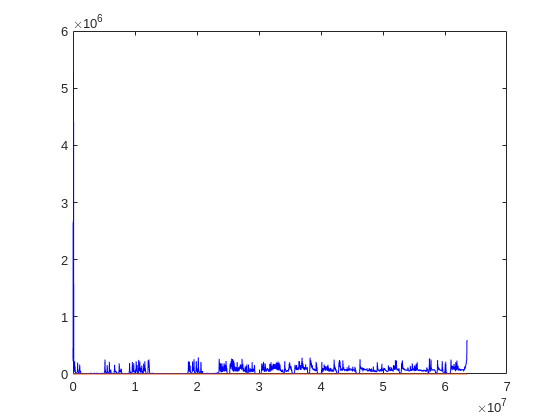

for i = 1:most_events
    try
        startXAl = experiment.conditionVector.aluminumEpochs(i, 1);
        endXAl = experiment.conditionVector.aluminumEpochs(i, 2);
        fill([startXAl, endXAl, endXAl, startXAl], [0, 0, maxY, maxY],'r','FaceColor',colorBen.aluminum,'FaceAlpha',0.2,'EdgeColor','none');
    end
    try
        startXAt = experiment.conditionVector.mutedEpochs(i, 1);
        endXAt = experiment.conditionVector.mutedEpochs(i, 2);
        fill([startXAt, endXAt, endXAt, startXAt], [0, 0, maxY, maxY],'b','FaceColor',colorBen.muted, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
    try
        startXNo = experiment.conditionVector.nonEpochs(i, 1);
        endXNo = experiment.conditionVector.nonEpochs(i, 2);
        fill([startXNo, endXNo, endXNo, startXNo], [0, 0, maxY, maxY],'y','FaceColor',colorBen.non, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
    try
        startXNW = experiment.conditionVector.noWhiskingEpochs(i, 1);
        endXNW = experiment.conditionVector.noWhiskingEpochs(i, 2);
        fill([startXNW, endXNW, endXNW, startXNW], [0, 0, maxY, maxY],'y','FaceColor',colorBen.purple, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
end

% extract FR across conditions for the table
FR_aluminum = experiment.Units.perCondition.aluminum.FR

FR_aluminum =     1.2465
   23.1765
    2.4828
    3.8915
    6.1412
   26.9363
   11.9784
    5.4825
    6.0500
   19.1432


FR_attenuated = experiment.Units.perCondition.muted.FR

FR_attenuated =     1.8703
   23.7276
    3.1544
    5.5085
    7.1090
   24.7512
   10.1424
    5.2201
    5.1270
   21.4386


FR_noObject = experiment.Units.perCondition.non.FR

FR_noObject =     6.0827
   23.2118
    5.0211
    2.9266
    5.4515
   17.7747
    7.6464
    5.2219
    3.8304
   19.0945


FR_NoWhisking = experiment.Units.perCondition.noWhisking.FR

FR_NoWhisking =     1.8845
   20.9275
    5.1835
    4.5771
    4.8671
   11.1772
    6.2419
    2.3539
    1.3887
   14.0006


% extract sub conditions for no whisking
FR_NoWhisking_aluminum = experiment.Units.perCondition.noWhisking.aluminum.FR

FR_NoWhisking_aluminum =     1.5614
   17.7039
    3.3900
    3.2356
    3.6215
   10.0007
    6.2159
    2.4935
    1.0983
   13.6163


FR_NoWhisking_attenuated = experiment.Units.perCondition.noWhisking.attenuated.FR

FR_NoWhisking_attenuated =     1.3373
   15.6716
    3.3553
    3.4114
    4.0200
   11.2325
    6.1902
    2.3650
    1.4174
   14.4998


FR_NoWhisking_noObject = experiment.Units.perCondition.noWhisking.noObject.FR

FR_NoWhisking_noObject =     1.7522
   20.7660
    4.2540
    3.5388
    3.5904
    9.5966
    6.4780
    2.3125
    1.3271
   13.4917


[AluminumSDF,AluminumBinnedFR,AluminumSTD,aluminumSamples] = getSDFs(experiment.conditionVector.aluminumEpochs,experiment.Units.perCondition.aluminum.times,20)

AluminumSDF = 15×1 cell array
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}


AluminumBinnedFR = 15×1 cell array
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}
    {98672×1 double}


AluminumSTD =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


aluminumSamples = 98672×1 int64 column vector
   18013090
   18013120
   18013150
   18013180
   18013210
   18013240
   18013270
   18013300
   18013330
   18013360


[AttenuatedSDF,AttenuatedBinnedFR,AttenuatedSTD,attenuatedSamples] = getSDFs(experiment.conditionVector.mutedEpochs,experiment.Units.perCondition.muted.times,20)

AttenuatedSDF = 15×1 cell array
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}


AttenuatedBinnedFR = 15×1 cell array
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}
    {107463×1 double}


AttenuatedSTD =   114.8011
  261.1829
  163.9452
  221.5327
  123.1876
  132.6769
   63.9779
   26.1637
   10.6843
  147.1670


attenuatedSamples = 107463×1 int64 column vector
   11198317
   11198347
   11198377
   11198407
   11198437
   11198467
   11198497
   11198527
   11198557
   11198587


[NoObjectSDF,NoObjectBinnedFR,noObjectSTD,NoObjectSamples] = getSDFs(experiment.conditionVector.nonEpochs,experiment.Units.perCondition.non.times,20)

NoObjectSDF = 15×1 cell array
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}


NoObjectBinnedFR = 15×1 cell array
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}
    {69700×1 double}


noObjectSTD =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


NoObjectSamples = 69700×1 int64 column vector
   8273328
   8273358
   8273388
   8273418
   8273448
   8273478
   8273508
   8273538
   8273568
   8273598


[NoWhiskingSDF,NoWhiskingBinnedFR,NoWhiskingSTD,NoWhiskingSamples] = getSDFs(experiment.conditionVector.noWhiskingEpochs,experiment.Units.perCondition.noWhisking.times,20)

NoWhiskingSDF = 15×1 cell array
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}


NoWhiskingBinnedFR = 15×1 cell array
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}
    {1437896×1 double}


NoWhiskingSTD =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


NoWhiskingSamples = 1437896×1 int64 column vector
   7715814
   7715844
   7715874
   7715904
   7715934
   7715964
   7715994
   7716024
   7716054
   7716084


% Create a reference table for the units 
unitID = [experiment.Units.good.id;experiment.Units.mua.id]

unitID =     48
    50
    56
    60
    65
    67
    73
    82
    83
    84


unitType = categorical([repmat("good",length(experiment.Units.good.id),1);repmat("mua",length(experiment.Units.mua.id),1)])

unitType = 15×1 categorical array
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 


Session = repmat({experiment.experiment_ID},length(unitID),1)

Session = 15×1 cell array
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}
    {'FVB111_715'}


referance_table = table(unitID,unitType,Session,FR_aluminum,FR_attenuated,FR_noObject,FR_NoWhisking, ...
    FR_NoWhisking_aluminum,FR_NoWhisking_attenuated,FR_NoWhisking_noObject ...
    ,AluminumSDF,AttenuatedSDF,NoObjectSDF,NoWhiskingSDF,AluminumBinnedFR,AttenuatedBinnedFR, ...
    NoObjectBinnedFR,NoWhiskingBinnedFR,AluminumSTD,AttenuatedSTD,noObjectSTD,NoWhiskingSTD)

referance_table = 15×22 table
    unitID    unitType       Session        FR_aluminum    FR_attenuated    FR_noObject    FR_NoWhisking    FR_NoWhisking_aluminum    FR_NoWhisking_attenuated    FR_NoWhisking_noObject      AluminumSDF         AttenuatedSDF        NoObjectSDF         NoWhiskingSDF       AluminumBinnedFR    AttenuatedBinnedFR    NoObjectBinnedFR    NoWhiskingBinnedFR    AluminumSTD    AttenuatedSTD    noObjectSTD    NoWhiskingSTD
    ______    ________    ______________    ___________    _____________    ___________

filename = [experiment.experiment_ID,'.mat']

filename = 'FVB111_715.mat'


tblFileName = ['condUnits_',filename]

tblFileName = 'condUnits_FVB111_715.mat'

% save(filename,'experiment','-v7.3')
% save(tblFileName,'referance_table','adjustedSamples','conditionVector')


adjustedSamples.Aluminum = aluminumSamples;
adjustedSamples.Attenuated = attenuatedSamples;
adjustedSamples.noObject = NoObjectSamples;
adjustedSamples.NoWhisking = NoWhiskingSamples;

conditionVector = experiment.conditionVector

conditionVector = struct with fields:
         aluminumEpochs: [17×2 int64]
            mutedEpochs: [13×2 int64]
              nonEpochs: [9×2 int64]
       noWhiskingEpochs: [234×2 int64]
               aluminum: [18013090 18013091 18013092 18013093 18013094 18013095 18013096 18013097 18013098 18013099 18013100 18013101 18013102 18013103 18013104 18013105 18013106 18013107 18013108 18013109 18013110 18013111 18013112 18013113 18013114 … ]
                  muted: [11198317 11198318 11198319 11198320 11198321 11198322 11198323 11198324 11198325 11198326 11198327 11198328 11198329 11198330 11198331 11198332 11198333 11198334 11198335 11198336 11198337 11198338 11198339 11198340 11198341 … ]
                    non: [8273328 8273329 8273330 8273331 8273332 8273333 8273334 8273335 8273336 8273337 8273338 8273339 8273340 8273341 8273342 8273343 8273344 8273345 8273346 8273347 8273348 8273349 8273350 8273351 8273352 8273353 8273354 8273355 … ]
             noWhisking: [7715814 7715815 7715

alignedTimes = experiment.timeStamp

alignedTimes = struct with fields:
           ephys: [3508 66504326]
         avisoft: [155459 554393640]
      alignedAvi: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]
    alignedEphys: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]


save(filename,'experiment','-v7.3')

save(tblFileName,'referance_table','adjustedSamples','conditionVector','alignedTimes',"-append")      


function [SDFs,unitVecBinned,unitSTD,samplesBinned] = getSDFs(conditionEpochs,unitsStruct,sigma)
% use condition spike times and condition epochs to generate a SDF for all
% units. sigma should be in units of ms.
    SDFs = cell(length(unitsStruct),1);
    edges = [-3*sigma:1:3*sigma];
    kernel = normpdf(edges,0,sigma)*1000;
    binSize = 30;
    unitVecBinned = cell(length(unitsStruct),1);
    unitSTD = [];
    samplesBinned = [];
    
    for ep = 1:size(conditionEpochs)
        discard = 0;
        epTimes = [conditionEpochs(ep,1):conditionEpochs(ep,2)];
        indexBuffer = buffer(epTimes, 30, 0,"nodelay");
        if any(indexBuffer(:,end) == 0)
            indexBuffer(:,end) = [];
            discard = 1;
        end
        samplesBinned = [samplesBinned,indexBuffer(1,:)];
        for un = 1:length(unitsStruct)
            %unitVbinned = [];
            %SDFV = [];
            unitTrain = unitsStruct{un};
            unitTemp = ismember(epTimes,unitTrain);
            unitBuffer = buffer(unitTemp, 30, 0,"nodelay");
            binnedSpikeTrain = sum(unitBuffer);
            if discard == 1
                binnedSpikeTrain(end) = [];
            end
            SDFtemp = conv(binnedSpikeTrain,kernel,'same');
            SDFs{un,1} = [SDFs{un,1};SDFtemp'];
            unitVecBinned{un,1} = [unitVecBinned{un,1};binnedSpikeTrain'];
            unitSTD(un) = std(binnedSpikeTrain*1000);
        end
    end
    unitSTD = unitSTD';
    samplesBinned = samplesBinned';
end
function intersections = getIntersct(experiment,condType)
                intersections = [];
                condA = experiment.conditionVector.noWhiskingEpochs;
                condB = experiment.Conditions.all_changesClean(experiment.Conditions.classificationCleaned == condType,:);
                for i = 1:size(condA,1)
                    for j = 1:size(condB,1)
                        % Check if condB(j,:) is entirely within condA(i,:)
                        if condB(j,1) >= condA(i,1) && condB(j,2) <= condA(i,2)
                            intersections = [intersections; condB(j,1) condB(j,2)];
                            % Check if condA(i,:) is entirely within condB(j,:)
                        elseif condA(i,1) >= condB(j,1) && condA(i,2) <= condB(j,2)
                            intersections = [intersections; condA(i,1) condA(i,2)];
                            % Check for any other overlaps
                        else
                            overlapStart = max(condA(i,1), condB(j,1));
                            overlapEnd = min(condA(i,2), condB(j,2));
                            if overlapStart < overlapEnd
                                intersections = [intersections; overlapStart overlapEnd];
                            end
                        end
                    end
                end
end


function intersectVector = condVector(conditionVect)
intersectVector = [];
for i = 1:size(conditionVect,1)
    intersectVector = [intersectVector, conditionVect(i,1):conditionVect(i,2)];
end
end
% 
%     for un = 1:length(unitsStruct)
%         unitVbinned = [];
%         SDFV = [];
%         unitTrain = unitsStruct{un};
%         for ep = 1:size(conditionEpochs)
%             epTimes = [conditionEpochs(ep,1):conditionEpochs(ep,2)];
%             unitTemp = ismember(epTimes,unitTrain);
% 
%             paddedSpiketrain = [unitTemp,zeros(1,padding)];
%             binnedSpikeTrain = sum(reshape(paddedSpiketrain,binSize,[]));
%             unitVbinned = [unitVbinned,binnedSpikeTrain];
%             SDFtemp = conv(binnedSpikeTrain,kernel,'same');
%             SDFV = [SDFV,SDFtemp];
%         end
%         SDFs{un,1} = SDFV';
%         unitVecBinned{un,1} = unitVbinned';
%         unitSTD(un) = std(unitVbinned*1000);
%     end
%     unitSTD = unitSTD';
%     samplesBinned = samplesBinned';
% end


